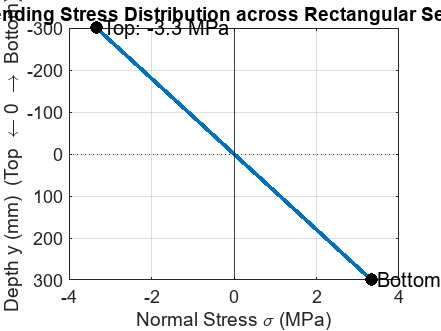

%% Bending Stress Distribution for a Rectangular Section

%% Section & Loading
b = 0.30;                 % width (m)
h = 0.60;                 % depth (m)
I = (b*h^3)/12;           % m^4

M = 60e3;                 % Bending moment (N·m); +ve -> tension at bottom (y>0)
                           % Flip sign to swap tension/compression sides.

%% Stress distribution
y = linspace(-h/2, h/2, 400);   % y measured from NA (center), +ve downward (plotting convenience)
sigma = (M .* y) ./ I;          % Pa

%% Extreme fiber stresses
sigma_top = (M*(-h/2))/I;       % top fiber (y = -h/2)
sigma_bot = (M*( h/2))/I;       % bottom fiber (y =  h/2)

%% Plot
figure;
plot(sigma/1e6, y*1e3, 'LineWidth', 2); hold on;
xline(0,'k-'); yline(0,'k:');
set(gca,'YDir','reverse'); % depth downward visually
xlabel('Normal Stress \sigma (MPa)');
ylabel('Depth y (mm)  (Top  \leftarrow 0  \rightarrow  Bottom)');
title('Bending Stress Distribution across Rectangular Section');
grid on; box on;

% Mark extreme fibers
plot([sigma_top sigma_bot]/1e6, [-h/2 h/2]*1e3, 'ko', 'MarkerFaceColor','k');
text(sigma_top/1e6, (-h/2)*1e3, sprintf(' Top: %.1f MPa', sigma_top/1e6), ...
     'VerticalAlignment','middle','HorizontalAlignment','left');
text(sigma_bot/1e6, ( h/2)*1e3, sprintf(' Bottom: %.1f MPa', sigma_bot/1e6), ...
     'VerticalAlignment','middle','HorizontalAlignment','left');


% Print to console
fprintf('Section b=%.0f mm, h=%.0f mm\n', b*1e3, h*1e3);

Section b=300 mm, h=600 mm


fprintf('I = %.3e m^4,  M = %.1f kN·m\n', I, M/1e3);

I = 5.400e-03 m^4,  M = 60.0 kN·m


fprintf('Extreme fiber stresses: Top = %.1f MPa, Bottom = %.1f MPa\n', sigma_top/1e6, sigma_bot/1e6);

Extreme fiber stresses: Top = -3.3 MPa, Bottom = 3.3 MPa
